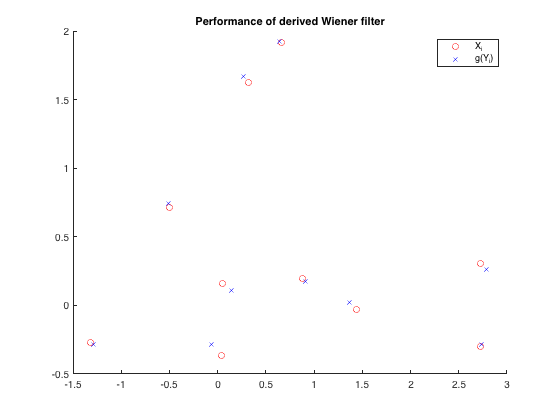

% Ben Juarez - PS4Q3b
n = 10;
G = [1 2; 3, 4]; % gain matrix
e = 0.03; 
X = zeros(0,2);
X_hat = zeros(0,2);

for i = 1:n
     x = normrnd(0,1,2,1); % standard normal
     X = [X;x']; % inputs X_i
     
     Y = G*x + mvnrnd([0;0],[e^2 0;0 e^2])'; % Y = GX + W
     u_x = [0;0]; % mean
     sig_x = [1 0; 0 1]; % covariance matrix X
     sig_w = [e^2 0; 0 e^2]; % covariance matrix W
     g = sig_x*G'*inv(G*sig_x*G'+sig_w)*(Y-G*u_x)+u_x; % g(Y)
     X_hat = [X_hat; g']; % estimates g(Y_i)
end

hold on
scatter(X(:,1), X(:,2), "red")
scatter(X_hat(:,1), X_hat(:,2), "blue", "x")
legend("X_i", "g(Y_i)")
title("Performance of derived Wiener filter")
hold off